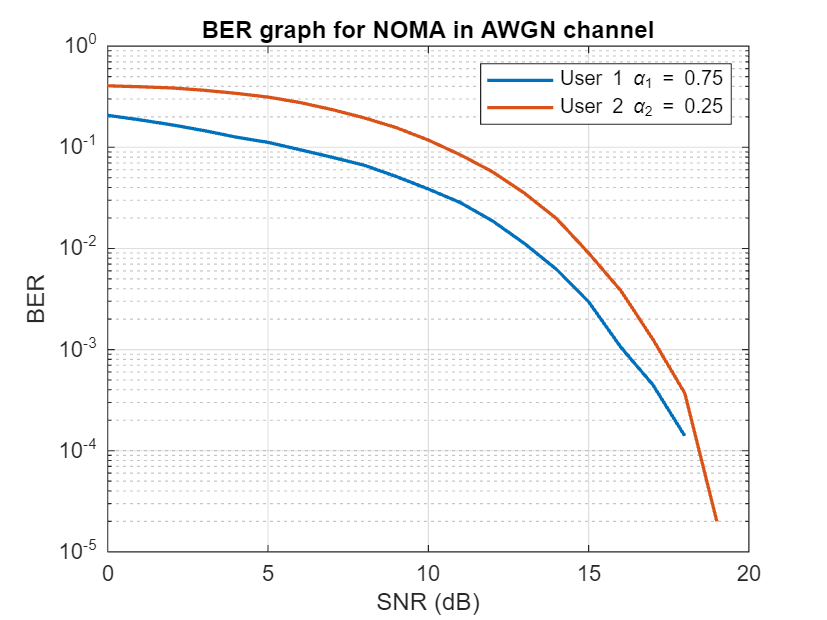

clc; clear variables; close all;
N = 10^5; %Number of monte carlo simulations
SNR = 0:30; %SNR range in dB
snr = db2pow(SNR); %SNR range in linear scale
%Generate random data bits for transmission
x1 = randi([0 1],1,N); %Data bits of user 1
x2 = randi([0 1],1,N); %Data bits of user 2
%Do BPSK modulation of data
xmod1 = 2*x1 - 1;
xmod2 = 2*x2 - 1;
%Set power weights for users
a1 = 0.8; a2 = 0.2;
%Do superposition coding
x = sqrt(a1)*xmod1 + sqrt(a2)*xmod2;
%Add AWGN to x (Transmit x through an AWGN channel)
for u = 1:length(snr)
y1 = awgn(x,SNR(u),'measured'); %Received signal at user 1 corrupted by AWGN
y2 = awgn(x,SNR(u),'measured'); %Received signal at user 2 corrupted by AWGN
%AT USER 1
%Direct decoding of x from y1
x1_hat = ones(1,N); %just a buffer
x1_hat(y1 < 0) = 0; %AT USER 2 %Direct decoding of x from y2 
x11_est = ones(1,N); %just a buffer 
x11_est(y2 < 0) = 0; %Estimate user 1's signal first 
x11_est(x11_est == 0) = -1; %Remodulate user 1's signal %Subtract remodulated x11_est component from y2 
rem = y2 - sqrt(a1)*x11_est; %Decode x2 from rem 
x2_hat = zeros(1,N); x2_hat(rem>0) = 1;
%Estimate BER
ber1(u) = biterr(x1,x1_hat)/N;
ber2(u) = biterr(x2,x2_hat)/N;
end
%plot BER curves
semilogy(SNR, ber1, 'linewidth', 1.5); hold on;
semilogy(SNR, ber2, 'linewidth', 1.5); grid on;
legend('User 1 \alpha_1 = 0.75','User 2 \alpha_2 = 0.25');
xlabel('SNR (dB)');
ylabel('BER');
title('BER graph for NOMA in AWGN channel')